# **Task_04:**   Design a Vibration Absorber tuned to the ORIGINAL structure's resonance

For our single floor tower:

- We'll design a vibration Absorber that attenuates vibrations at the ORIGINAL structure's resonant frequency

For some Background on the Design process see:

- [`bh_FUNDAMENTALS_ABSORBER_background.pdf `](matlab:  winopen bh_fundamentals_absorber_background.pdf)

-  [`TASK_00_revise_vibration_absorber_concept.mlx`](matlab:  open  TASK_00_revise_vibration_absorber_concept.mlx)

So what you should see is that the **Vibration Absorber** attenuates the **Modified structure's** response when we excite it at the resonant frequency of the **ORIGINAL structur**e - as shown below

## Clear the workspace

clear

## Load the STANDARD model parameters

STANDARD_params_single_tower

whos

  Name               Size            Bytes  Class                       Attributes

  col_OBJ            1x1               286  bh_flex_column_CLS                    
  earth_vis_OBJ      1x1                72  earth_vis_CLS                         
  floor_OBJ          1x1                32  bh_solid_floor_CLS                    
  params_dB          1x1              9689  bh_flex_tower_params_CLS              



## Configure for this TEST

Define column damping

col_OBJ.damp_ratio = 1e-1;  %params_dB.col_damp_ratio;

## Define the excitation frequency

Recall the resonant frequency of the **ORIGINAL** system:

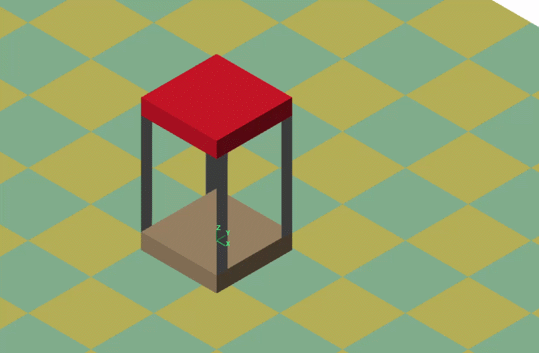

load("bh_SYS_ID_RESULTS.mat","wn_radpersec_original_building");

w_reson    = wn_radpersec_original_building;
f_hz_reson = w_reson/(2*pi)

f_hz_reson = 2.4298

## Design the Absorber

Let's implement the standard (?) vibration design formula:

- $m_a \;\;=\;\;\;\frac{k_a }{\omega_{\mathrm{DES}}^2 \;}$       where   $\omega_{\mathrm{DES}}$ is the design frequency at which we want to attenuate  the amplitude of the systems vibration

We'll specify the absorber's mass $\left(m_a \right)$ and then compute it's stiffness $\left(k_a \right)$ using our design formula.

absorber_params_T.ma = 0.025; % (kg)
absorber_params_T.ka = w_reson^2 * absorber_params_T.ma; % (N/m)
absorber_params_T.La = floor_OBJ.WIDTH/2;  % (m)
absorber_params_T.ca = 0.005;  % (N/(m/s))

## Some Simscape visualization artifacts

I'll insert some light weight cylinders to denote the springs - this is **for visualization purposes only** and will have almost no effect on the system dynamics (e.g.:   mass = ${10}^{-10} \;$kg)

vis_itemT.r = 0.05 * 0.1;          %(m)
vis_itemT.L = absorber_params_T.La/4; %(m)
params_T.m  = 1e-10;          % (kg)

## Now open the Simulink model

When the Simulink model opens ... run it.  

And compare the response of the building WITH and withOUT a Vibration Absorber

open_system("bh_single_tower_ABSORBER_test.slx")